# WLAN MAC Basics - Custom Channel Model

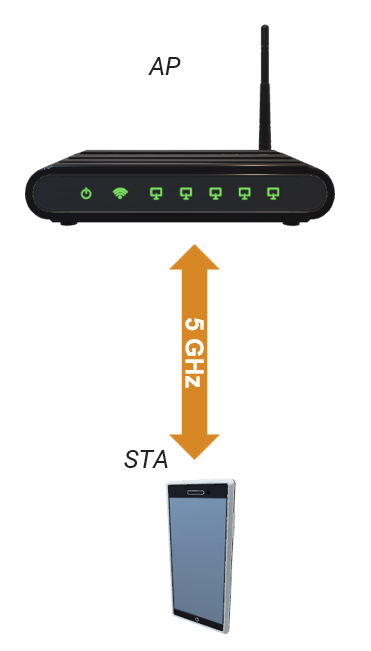

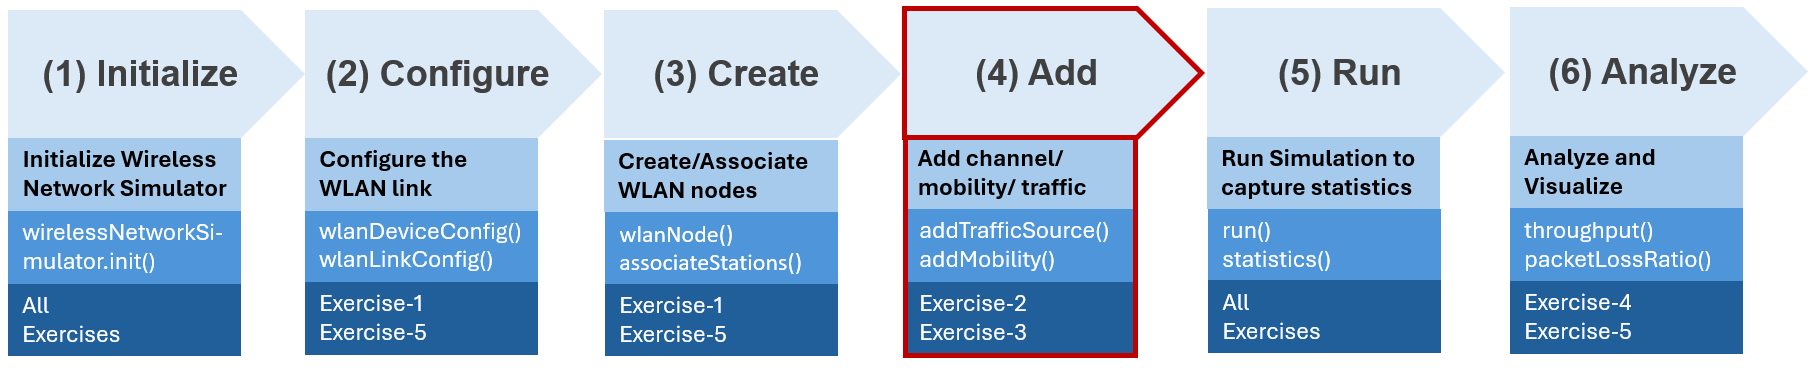

Workflow to perform WLAN Network Modeling

- Implement a channel model in 1/R^3

Copyright 2024-2025 The MathWorks, Inc

clear;
format shortEng;
% Set seed of random number generator for reproducible results
rng(1,"combRecursive");

### Physical constants and environment

band    = 5;
channel = 36;
channelBandwidth    = 20e6;
fc      = wlanChannelFrequency(channel,band)

TU              = 1024e-6;
simulationTime  = 10*TU

txPower = 0.0;
txGain  = 0.0;

APPosition  = [0,0,0];
STAPosition = [1.0, 0.0, 0.0];
D           = norm(STAPosition-APPosition)

### Create an instance of Wireless Network Simulator

networkSimulator = wirelessNetworkSimulator.init;

### Attenuation in 1/R^3

- Reference value


$$\textrm{pathLoss}={\left(\frac{4\pi R}{\lambda }\right)}^3$$


attR3 = 10*log10(((4*pi*D)/(3e8/fc))^3)
plotStations (APPosition,STAPosition,fc);

### Create AP

- 802.11n type

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat","HT-Mixed", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower",txPower, ...
    "TransmitGain",txGain, ...
    "MCS",3, ...
    "BeaconInterval",1, ...
    "InitialBeaconOffset",0);

AP = wlanNode(...
    "Name","AP",...
    "Position",APPosition, ...
    "DeviceConfig",APCfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Create STA

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","Non-HT", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",channelBandwidth,...
    "TransmitPower",txPower, ...
    "MCS",3, ...
    "ReceiveGain",0);

STA = wlanNode(...
    "Name","STA",...
    "Position",STAPosition, ...
    "DeviceConfig",STACfg,...
    "MACFrameAbstraction",false,...
    "PHYAbstractionMethod","tgax-evaluation-methodology");

### Associate AP with STA

associateStations(AP,STA)

# Task #1/4 Add Custom Channel Model to Network Simulator

% Use addChannelModel() function to define a function implementing a propagation channel model
% Hint: Click the link below and see the "Syntax" section.

### [Help on adding custom channel ](https://www.mathworks.com/help/releases/R2024b/comm/ref/wirelessnetworksimulator.addchannelmodel.html)

% Note : name the function implememint the channel "myCustomChannel". To
% pass the function as an argument use @myCustomChannel 

% <enter code below>
%

% Goto the end of this script to define myCustomchannel () function

#### Run the simulation

addNodes(networkSimulator,{AP, STA})
run (networkSimulator,simulationTime)

networkSimulator.ChannelFunction

### Visualize statistics

STAStatistics = statistics(STA)
STAStatistics.MAC;

#### Custom channel

Attenuation in 1/R^3;  $\mathrm{pathLoss}={\left(\frac{4\pi R}{\lambda }\right)}^3$

# Task #2/4 Put a breakpoint inside "myCustomChannel" to see the input arguments 

% myCustomChannel is a user-defined callback function invoked by the simulation engine
% whenever a packet is exchanged between any two nodes in the simulated network.

% rxInfo that passed to this function constains the following information
    % ID
    % Position
    % Velocity and more .. 
% txData that is passed function constains the following information
    % TransmitterID
    % TransmitterPosition
    % TransmitterVelocity
    % Power
    % CenterFrequency
    % Bandwidth
    % Data and more ..

function outputData = myCustomChannel(rxInfo,txData)

% Works only for SISO
if (txData.NumTransmitAntennas > 1 || rxInfo.NumReceiveAntennas > 1)
    coder.internal.error('wirelessnetwork:wirelessNetworkSimulator:NoMIMOInDefaultChannel')
end

outputData = txData;

# Task #3/4 Calculate the distance between transmitter and receiver in meters

% Use norm() function to compute distance between AP and STA
% a = [0 3 1];
% b = [-2 1 5];
% d = norm(b-a)
% Hint: see the contents of outputData.TransmitterPosition, rxInfo.Position
% name the variable "distance"

% <enter code below>
% distance = 

# Task #4/4 Calculate free space path loss proportional R^3 

lambda = 3e8/(outputData.CenterFrequency);
% Calculate path loss (in dB)
% Use this formula "10*log10(((4*pi*D)/(3e8/fc))^3)"
% name the variable "pathLoss"

% <enter code below>
% pathLoss = 

% Apply path loss on the power of the packet
outputData.Power = outputData.Power - pathLoss;

if outputData.Abstraction == 0
    % Apply the path loss effect on IQ samples
    scale = 10.^(-pathLoss/20);
    [numSamples, ~] = size(outputData.Data);
    outputData.Data(1:numSamples,:) = outputData.Data(1:numSamples,:)*scale;
end

% Set Metadata
outputData.Metadata.Channel.PathGains   = 1;
outputData.Metadata.Channel.PathDelays  = 0;
outputData.Metadata.Channel.PathFilters = 1;
outputData.Metadata.Channel.SampleTimes = 0;

%disp(outputData.Metadata.Channel)
end

#### Suggested Experiment:

#### #1

#### Refer to the provided table to adjust the following parameters:

- **For the scenario where the AP (Access Point) generates only beacon frames, set the AP’s position to **`[0, 0, 0]`** and the STA’s (Station) position to **`[5, 5, 0]`**.**

- **Increase the distance between the AP and STA so that the total attenuation causes the received signal to fall below the receiver’s minimum input sensitivity level.**